# **Regression**

#### **1.Bike Sharing**

# Dataset Characteristics

Multivariate

# Subject Area

Social Science

# Associated Tasks

Regression

# Attributes :

**Attributes (Columns):**

**Instant**:

- Record index (unique identifier for each entry).

**Dteday**:

- Date of the record (in YYYY-MM-DD format).

**Season**:

- The season of the year (1: spring, 2: summer, 3: fall, 4: winter).

**Yr**:

Year (0: 2011, 1: 2012).

**Mnth**:

- Month (1 to 12).

**Hour**:

- Hour of the day (0 to 23).

**holiday**:

- Whether the day is a holiday (1: yes, 0: no).

**Weekday**:

- Day of the week (0: Sunday, 1: Monday, ..., 6: Saturday).

**Workingday**:

- Whether the day is a working day (1: yes, 0: no).

**Weather**:

- Weather condition (1: clear, 2: cloudy, 3: light rain/snow, 4: heavy rain/snow).

**Temp**:

- Temperature in Celsius, normalized to a value between 0 and 1.

**Atemp**:

- "Feels like" temperature in Celsius, normalized.

**Hum**:

- Humidity in percentage (0 to 1).

**Windspeed**:

- Windspeed in kilometers per hour, normalized.

**Casual**:

- Count of casual riders (not registered users).

**Registered**:

- Count of registered riders.

**Count**:

- Total count of bike rentals (the target variable for prediction).

# Feature Type

Integer, Real

# # Instances

17389

# # Features

13

# DESCRIPTION :

The **Bike Sharing Dataset** from the UCI Machine Learning Repository provides information about the usage patterns of a bike-sharing system. It contains data collected from a two-year bike-sharing program, specifically designed to model the count of bikes rented in an hour or day. The dataset includes variables related to date and time, weather conditions, seasonal effects, and other environmental factors that influence bike rentals. Key features include the year, month, day, and hour of rental, temperature, humidity, wind speed, and weather conditions such as clear or rainy. Additionally, the dataset includes information about whether a given day is a holiday or weekend, as well as the type of season. The target variable, **count**, represents the total number of bike rentals for a specific period, while other variables separately track casual users and registered users.

clc, close all,clearvars;
% Load the dataset
data = readtable("Enter your file path");

% Step 2: Check and process non-numeric columns
% Identify numeric columns
numeric_columns = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
% Convert the table to an array using only numeric columns
data = table2array(data(:, numeric_columns));
data = fillmissing(data, 'constant', mean(data, 'omitnan'));
data=normalize(data);
X = data(:, 1:end-1); % Features
y = data(:, end);     % Target variable

% Split the data into training (80%) and testing (20%)
[m, ~] = size(X); % Number of rows in the dataset
trainSize = round(0.8 * m); % Number of training samples

% Training and testing split
XTrain = X(1:trainSize, :);   % First 80% of the rows for training
yTrain = y(1:trainSize);       % Corresponding target values
XTest = X(trainSize+1:end, :); % Remaining 20% of the rows for testing
yTest = y(trainSize+1:end);    % Corresponding target values

% Add bias term to features
XTrain = [ones(size(XTrain, 1), 1), XTrain]; % Add column of ones to training data
XTest = [ones(size(XTest, 1), 1), XTest];    % Add column of ones to testing data

% Compute weights using the pseudo-inverse
w = pinv(XTrain) * yTrain;

% Predict values for the test set
yPred = XTest * w;

% Compute performance metrics
rmse = sqrt(mean((yTest - yPred).^2)); % Root Mean Squared Error
mae = mean(abs(yTest - yPred));        % Mean Absolute Error

% Display the results
fprintf('Root Mean Squared Error (RMSE): %.4f\n', rmse);

Root Mean Squared Error (RMSE): 0.0000


fprintf('Mean Absolute Error (MAE): %.4f\n', mae);

Mean Absolute Error (MAE): 0.0000


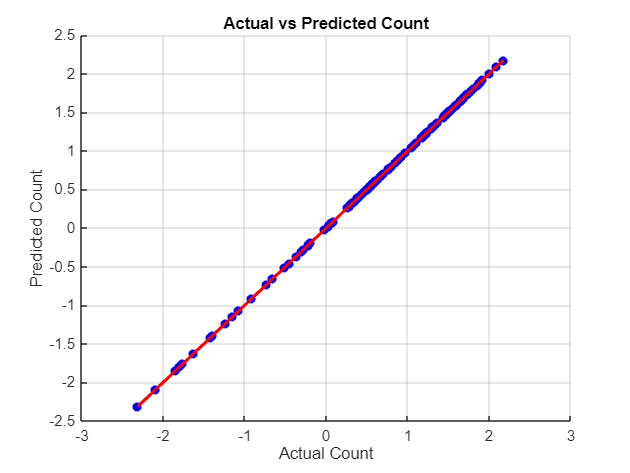


figure(2);
scatter(yTest, yPred, 'b', 'filled');
xlabel('Actual Count');
ylabel('Predicted Count');
title('Actual vs Predicted Count');
grid on;
hold on;
plot([min(yTest) max(yTest)], [min(yTest) max(yTest)], 'r-', 'LineWidth', 2); 

#### **2.Wine Quality (White)**

# Dataset Characteristics

Multivariate

# Subject Area

Business

# Attribute

**Fixed acidity**:

- The amount of fixed acids in the wine (e.g., tartaric acid). Measured in grams per liter (g/L).

**Volatile acidity**:

- The amount of volatile acids (e.g., acetic acid) in the wine. Measured in g/L.

**Citric acid**:

- The amount of citric acid in the wine. Measured in g/L.

**Residual sugar**:

- The amount of residual sugar left after fermentation, measured in g/L.

**Chlorides**:

- The amount of salt (chlorides) in the wine. Measured in g/L.

**Free sulfur dioxide**:

- The amount of free sulfur dioxide, which acts as a preservative. Measured in mg/L.

**Total sulfur dioxide**:

- The total amount of sulfur dioxide in the wine, including free and bound forms. Measured in mg/L.

**Density**:

- The density of the wine, which is related to the alcohol content. Measured in g/cm³.

**pH**:

- The pH level of the wine, which indicates its acidity.

**Sulphates**:

- The amount of sulphates in the wine. Measured in g/L.

**Alcohol**:

- The alcohol content in the wine, measured in percentage of alcohol by volume.

**Quality** (target variable):

- The quality of the wine, measured on a scale from 0 to 10, based on expert sensory evaluations. This is a **regression** target in predicting the wine's quality.

# Associated Tasks

Classification, Regression

# Feature Type

Real

# # Instances

4898

# # Features

11

clc,clear all,close all;% Load the dataset
data = readtable("Enter your file path",'VariableNamingRule','preserve'); 

% Step 2: Check and process non-numeric columns
% Identify numeric columns
numeric_columns = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
% Convert the table to an array using only numeric columns
data = table2array(data(:, numeric_columns));
data = fillmissing(data, 'constant', mean(data, 'omitnan'));
data=normalize(data);
X = data(:, 1:end-1); % Features
y = data(:, end);     % Target variable

% Split the data into training (80%) and testing (20%)
[m, ~] = size(X); % Number of rows in the dataset
trainSize = round(0.8 * m); % Number of training samples

% Training and testing split
XTrain = X(1:trainSize, :);   % First 80% of the rows for training
yTrain = y(1:trainSize);       % Corresponding target values
XTest = X(trainSize+1:end, :); % Remaining 20% of the rows for testing
yTest = y(trainSize+1:end);    % Corresponding target values

% Add bias term to features
XTrain = [ones(size(XTrain, 1), 1), XTrain]; % Add column of ones to training data
XTest = [ones(size(XTest, 1), 1), XTest];    % Add column of ones to testing data

% Compute weights using the pseudo-inverse
w = pinv(XTrain) * yTrain;

% Predict values for the test set
yPred = XTest * w;

% Compute performance metrics
rmse = sqrt(mean((yTest - yPred).^2)); % Root Mean Squared Error
mae = mean(abs(yTest - yPred));        % Mean Absolute Error

% Display the results
fprintf('Root Mean Squared Error (RMSE): %.4f\n', rmse);

Root Mean Squared Error (RMSE): 0.8042


fprintf('Mean Absolute Error (MAE): %.4f\n', mae);

Mean Absolute Error (MAE): 0.6225


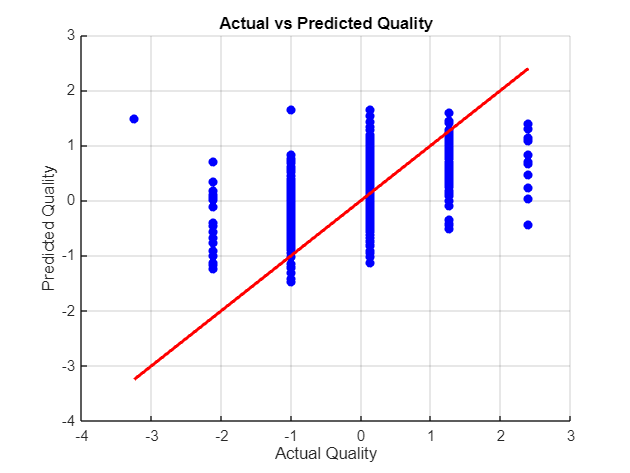


figure(2);
scatter(yTest, yPred, 'b', 'filled');
xlabel('Actual Quality');
ylabel('Predicted Quality');
title('Actual vs Predicted Quality');
grid on;
hold on;
plot([min(yTest) max(yTest)], [min(yTest) max(yTest)], 'r-', 'LineWidth', 2); 

#### **3.Auto MPG**

# Dataset Characteristics

Multivariate :

# Attributes :

**Mpg** (Miles per gallon):

- The fuel efficiency of the car (dependent/target variable for regression tasks).

**Cylinders**:

- The number of cylinders in the car's engine (e.g., 4, 6, 8).

**Displacement**:

- The engine displacement in cubic inches.

**Horsepower**:

- The horsepower of the car. Some values are missing and are represented as `?`.

**Weight**:

- The weight of the car in pounds.

**Acceleration**:

- The time it takes for the car to accelerate from 0 to 60 mph, in seconds.

**Model year**:

- The year the car model was released (e.g., 70 = 1970, 82 = 1982).

**Origin**:

- The origin of the car:

- 1 = USA

- 2 = Europe

- 3 = Japan

**Car name** (additional attribute in some formats):

- The name of the car (e.g., "chevrolet chevelle malibu").

# Associated Tasks

Regression

# Feature Type

Real, Categorical, Integer

# # Instances

398

# # Features

7

# Description:

The **Auto MPG dataset** is a classic dataset used for regression analysis, containing fuel efficiency data (miles per gallon, **mpg**) and characteristics of 398 cars from the 1970s and 1980s. Key attributes include engine cylinders, displacement, horsepower, weight, acceleration, model year, and origin. The dataset is ideal for regression models as it explores the relationship between **mpg** (dependent variable) and these features (independent variables). Its manageable size, multivariate nature, and presence of missing data in the `horsepower` column make it suitable for testing data preprocessing, feature engineering, and performance of regression techniques, providing insights into vehicle fuel efficiency trends.

clc;
clear all;
close all;

% Load the dataset
data = readtable("Enter your file path");

% Step 2: Check and process non-numeric columns
% Identify numeric columns
numeric_columns = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
% Convert the table to an array using only numeric columns
data = table2array(data(:, numeric_columns));
data = fillmissing(data, 'constant', mean(data, 'omitnan'));
data=normalize(data);
X = data(:, 2:end); % Features
y = data(:,1);     % Target variable

% Split the data into training (80%) and testing (20%)
[m, ~] = size(X); % Number of rows in the dataset
trainSize = round(0.8 * m); % Number of training samples

% Training and testing split
XTrain = X(1:trainSize, :);   % First 80% of the rows for training
yTrain = y(1:trainSize);       % Corresponding target values
XTest = X(trainSize+1:end, :); % Remaining 20% of the rows for testing
yTest = y(trainSize+1:end);    % Corresponding target values

% Add bias term to features
XTrain = [ones(size(XTrain, 1), 1), XTrain]; % Add column of ones to training data
XTest = [ones(size(XTest, 1), 1), XTest];    % Add column of ones to testing data

% Compute weights using the pseudo-inverse
w = pinv(XTrain) * yTrain;

% Predict values for the test set
yPred = XTest * w;

% Compute performance metrics
rmse = sqrt(mean((yTest - yPred).^2)); % Root Mean Squared Error
mae = mean(abs(yTest - yPred));        % Mean Absolute Error

% Display the results
fprintf('Root Mean Squared Error (RMSE): %.4f\n', rmse);

Root Mean Squared Error (RMSE): 0.3103


fprintf('Mean Absolute Error (MAE): %.4f\n', mae);

Mean Absolute Error (MAE): 0.2476


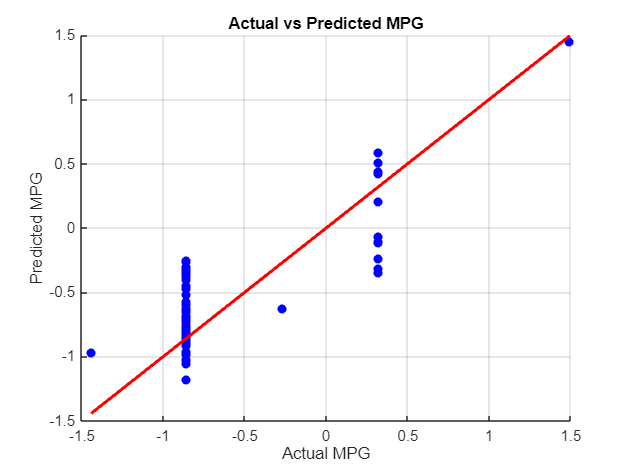


figure(1);
scatter(yTest, yPred, 'b', 'filled');
xlabel('Actual MPG');
ylabel('Predicted MPG');
title('Actual vs Predicted MPG');
grid on;
hold on;
plot([min(yTest) max(yTest)], [min(yTest) max(yTest)], 'r-', 'LineWidth', 2); 